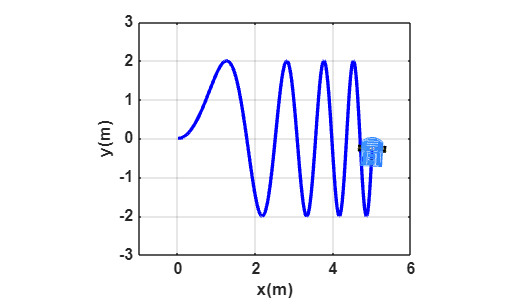

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%% TRAYECTORIA PERSONALIZADA %%%%%%%%%%%%%%%%%%%%%%%%%%%

x_range = linspace(0, 5, 300);       % Vector de X
y_range = 2 * sin(x_range.^2);       % Y = 2·sin(x²)

hx_square = x_range;
hy_square = y_range;

%%%%%%%%%%%%%%%%%%%%%% ORIENTACIÓN DEL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

phi_square = atan2(diff(hy_square), diff(hx_square));
phi_square(end+1) = phi_square(end);  % Igualar longitudes

x1_square = hx_square;
y1_square = hy_square;

N_square = length(x_range);
ts = 0.03;  % Tiempo de muestreo

%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN GRÁFICA %%%%%%%%%%%%%%%%%%%%%%%
scene1 = figure;
set(scene1,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene1,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([2]);
axis([-1 6 -3 3 0 2]);  % Ajustado al rango de la función

scale = 4;  % Tamaño del robot
MobileRobot_5; % Cargar modelo del robot
H1 = MobilePlot_4(x1_square(1), y1_square(1), phi_square(1), scale); hold on;
H2 = plot3(hx_square(1), hy_square(1), 0, 'b', 'lineWidth', 2);  % Trazo en azul

% Animación del movimiento
for k = 1:N_square
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1_square(k), y1_square(k), phi_square(k), scale);
    H2 = plot3(hx_square(1:k), hy_square(1:k), zeros(1,k), 'b', 'lineWidth', 2);
    pause(ts);
end